# BACKGROUND ON INTERPX algorithm

## Generate sample data

Generate a meshgrid and apply the peaks function to obtain a 3D interpolation for random values of x and y. We will then save this data for later.

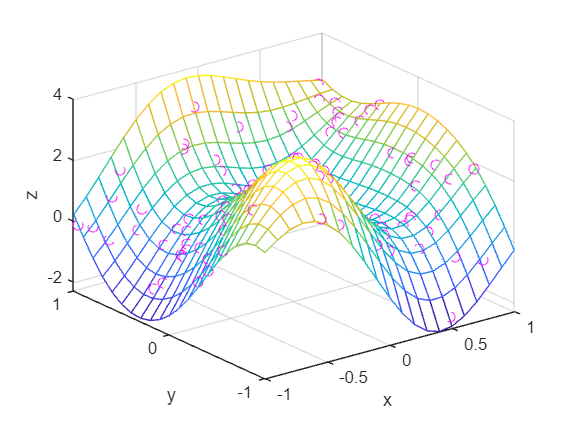

clear

[xm,ym] = meshgrid(-1:0.1:1,-1:0.1:1);
zm = peaks(xm,ym);
x = -1 + (1+1)*rand([100 1]);
y = -1 + (1+1)*rand([100 1]);
mesh(xm,ym,zm)
z = interp2(xm,ym,zm,x,y);
hold on;
plot3(x,y,z,'mo');
xlabel('x');
ylabel('y');
zlabel('z')
hold off;


save data x y z
clear




## Generate Delaunay Triangulation

Generate a triangulation matrix using delaunayn. Each row contains indices in [x,y] that correspond to the vertices of these triangles.

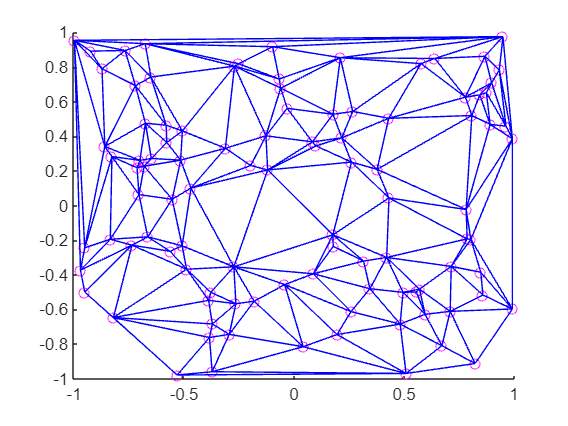

load data
scatter(x,y,'mo');
xyq = [x,y,z];

tes = delaunayn([x,y]);
hold on;
triplot(tes,x,y)
hold off;

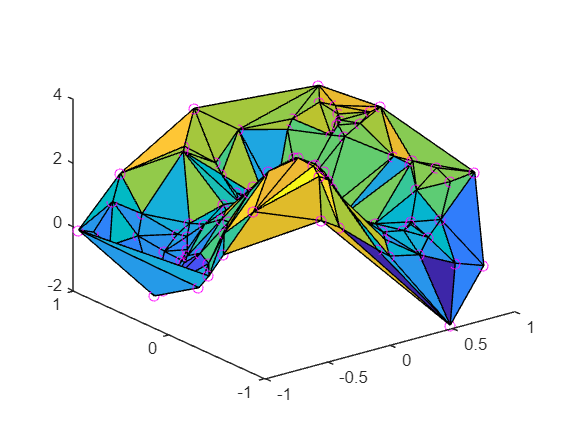


plot3(x,y,z,'mo');
hold on;
trisurf(tes,x,y,z);
hold off;

## Finding which triangle a given point occupies

We set a random point with the goal of having coloring that triangle green

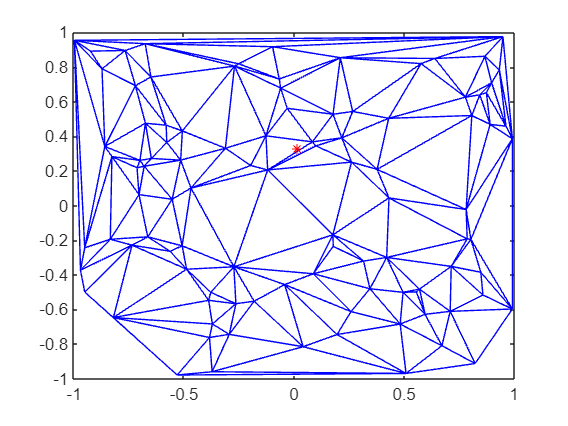

xi = -1 + (1+1)*rand([1 1]);
yi = -1 + (1+1)*rand([1 1]);
triplot(tes,x,y);
hold on;
plot(xi, yi,'r*');
hold off;

Find the triangle that encircles it in tes using convhull of the vertices of each triangle with the point. The convex hull of these points must never include the point.

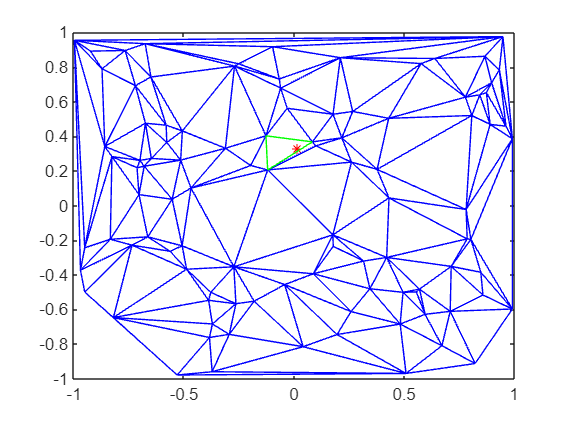

g = zeros([length(tes) 1]);
for idx = 1:length(tes) 
    rtri = tes(idx,:);
    rtri_points = xyq(rtri,1:2);
    k = convhull([rtri_points;xi,yi]);
    g(idx) = ~any(k==4);
end
idx = find(g);
rtri = tes(idx,:);
rtri_points = xyq(rtri,1:2);
rtrig = xyq(rtri,:);
k = convhull(rtri_points);

hold on
plot(rtri_points(k,1),rtri_points(k,2),"g-");
hold off

From here, you can define an approximate value for zi using the equation of the plane  and obtain a interpolation for z

A = rtrig(1,:);
B = rtrig(2,:);
C = rtrig(3,:);

AB = B-A;
AC = C-A;
n = cross(AB,AC)

n =     0.0963    0.0577    0.0413


zi = ((n(1)*A(1) + n(2)*A(2) +n(3)*A(3)) - n(1)*xi - n(2)*yi )/n(3)

zi = 0.4360

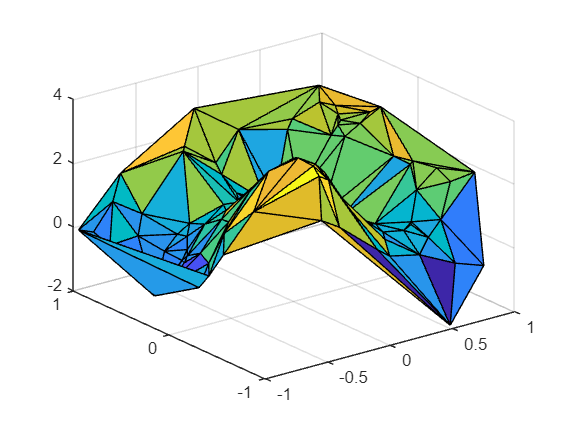


trisurf(tes,x,y,z);
hold on;
plot3(xi,yi,zi,'bo')
hold off;

Notice that if the point is outside the "net" of sample data, an error occurs. This also happens with griddata and can be ignored by setting z=Nan in this case.